## vna_reader.mlx

This program reads all the 'test' files in the current MATLAB directory, so be sure to open the correct folder on the left where the tests to be seen are.

It is the first attempt to take S21 data from a VNA and convert it into time-domain data. However, the results obtained from these plots are incorrect for reasons outlined in the report.

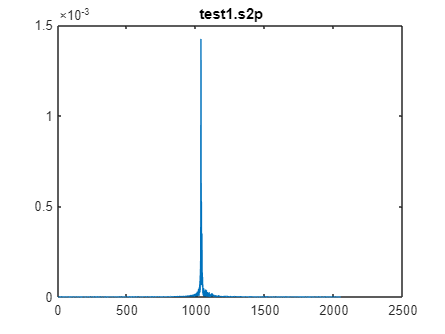

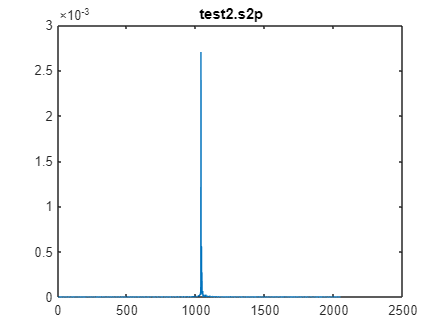

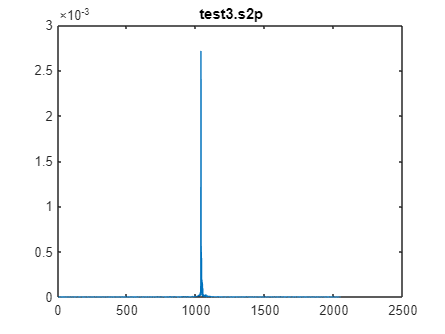

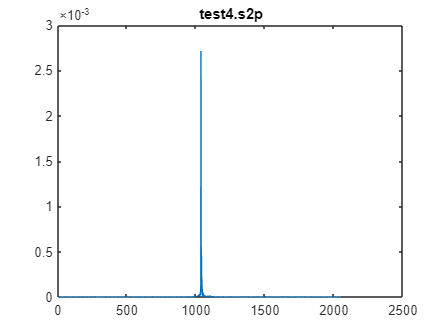

close all; clear;

% look for all the files named "testX.s2p"
% and open them as s-parameter objects in a list
fileprefix = "test";
directory = pwd;

% Get a list of all files in the directory
files = dir(fullfile(directory, [fileprefix + '*.s2p']));
% Determine the number of files found
numFiles = numel(files);

% Initialize a cell array to store the data from each file
dataCell = cell(1, numFiles);
figure;
for i = 1:numFiles
    % Construct the filename
    filename = fullfile(directory, files(i).name);
    
    % Read the data from the file
    % Use appropriate function based on your file format
    % For example, if your files are text files with numeric data:
    dataCell{i} = sparameters(filename);
    params = rfparam(dataCell{i}, 2, 1);
    data = params;
    data_flip = flipud(conj(data(2:end)));        
    data_total = [data_flip; data];  
    data_ifft = ifft(data_total, 2048, 'symmetric');    
    ifft_time = (ifftshift(abs(data_ifft)));

    %disp(dataCell{i})
    %figure;
    %rfplot(dataCell{i})
    %X = ifft(params, []);
    %t = linspace(0,[],length(params));
    figure;
    plot(abs(ifft_time))
    title(files(i).name)
end

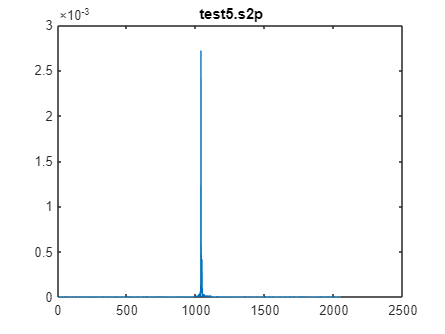

hold off;